clear
load("chips20.mat")
load("DLP.mat")
load("illum.mat")
load("Ramp_display.mat")
load("Ramp_linear.mat")
load("RGB_cal.mat")
load("RGB_raw.mat")
load("TRC_display.mat")
load("xyz.mat")
load("XYZ_est.mat")
load("XYZ_ref.mat")

% 1.1
clf
inputLinear = (0:0.01:1)'

inputLinear =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


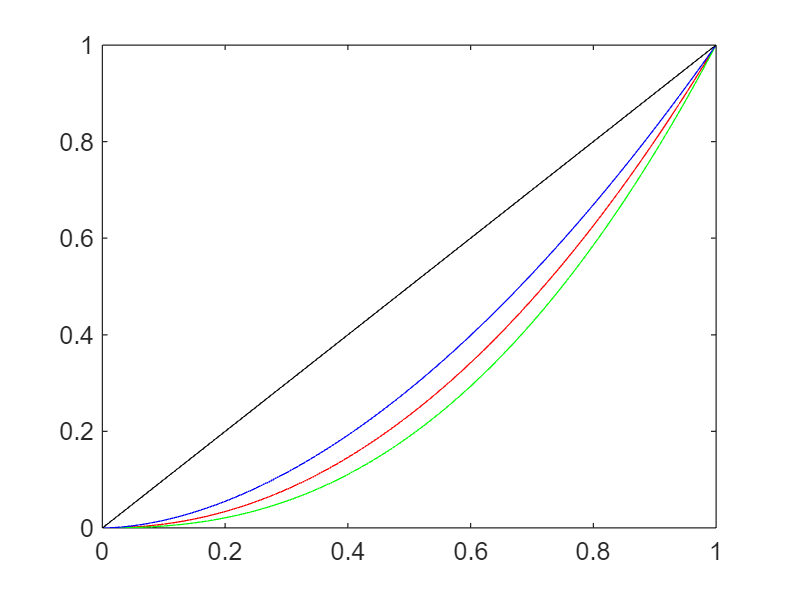

plot(inputLinear,TRCr', 'r')
hold on
plot(inputLinear, TRCg', 'g')
plot(inputLinear, TRCb', 'b')
plot(inputLinear, inputLinear, 'black')

TRCr

TRCr =          0    0.0001    0.0003    0.0006    0.0012    0.0019    0.0027    0.0038    0.0050    0.0064    0.0079    0.0097    0.0116    0.0138    0.0161    0.0186    0.0213    0.0242    0.0273    0.0306    0.0341    0.0377    0.0416    0.0457    0.0499    0.0544    0.0591    0.0640    0.0690    0.0743    0.0798    0.0855    0.0914    0.0975    0.1038    0.1103    0.1170    0.1239    0.1311    0.1384    0.1460    0.1538    0.1617    0.1699    0.1783    0.1870    0.1958    0.2048    0.2141    0.2236


1.1 Gamma curve is different and it will reflected as colour vibrancy? The colours will map to darker values 0.4-> 0.15

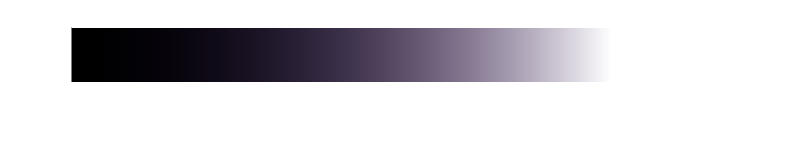

% 1.2

imshow(Ramp_display)

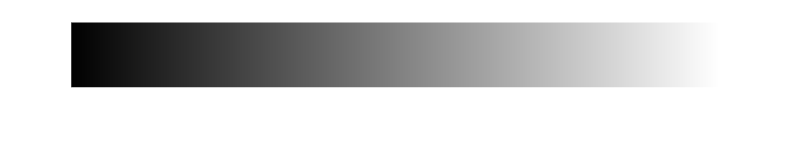

imshow(Ramp_linear)

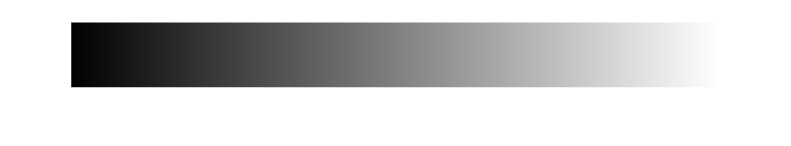


imshow(linearization(TRCr, TRCg, TRCb, Ramp_display))

%1.3 
clf
yr = 2.1

yr = 2.1000

yg = 2.4

yg = 2.4000

yb = 1.8

yb = 1.8000


Dmax = max(max(Ramp_display));

D(:,:,1) = (Dmax(:,:,1) * (Ramp_display(:,:,1) / Dmax(:,:,1)).^(1/yr));
D(:,:,2) = (Dmax(:,:,2) * (Ramp_display(:,:,2) / Dmax(:,:,2)).^(1/yg));
D(:,:,3) = (Dmax(:,:,3) * (Ramp_display(:,:,3) / Dmax(:,:,3)).^(1/yb));

imshow(D)

1.3 We managed to convert ramp_display to ramp_linear using eq 4 gamma equation. 

%2.1
clf
x = (400:5:700)

x =    400   405   410   415   420   425   430   435   440   445   450   455   460   465   470   475   480   485   490   495   500   505   510   515   520   525   530   535   540   545   550   555   560   565   570   575   580   585   590   595   600   605   610   615   620   625   630   635   640   645


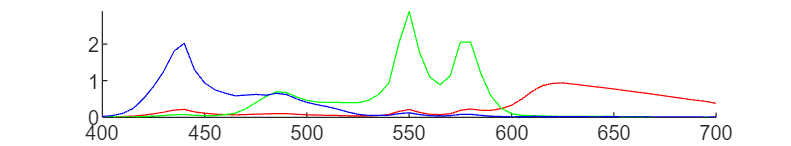


hold on
plot(x, DLP(:,1), "r")
plot(x, DLP(:,2), "g")
plot(x, DLP(:,3), "b")

2.1 Wow Max Wiklundh's mind was blown when the graph was completly different. We can see that intensity of red is overall lower than the other. Green has large peaks (human eye likes green). 

%2.2 
clf
DLP

DLP =     0.0081    0.0053    0.0254
    0.0125    0.0125    0.0463
    0.0204    0.0100    0.1103
    0.0328    0.0126    0.2447
    0.0589    0.0218    0.5066
    0.0955    0.0323    0.8443
    0.1413    0.0486    1.2600
    0.1973    0.0690    1.8094
    0.2166    0.0777    2.0202
    0.1480    0.0549    1.2996


Srgb = DLP * RGB_raw

Srgb =     0.0172    0.0077    0.0037    0.0055    0.0141    0.0108    0.0067    0.0018    0.0033    0.0012    0.0043    0.0035    0.0032    0.0028    0.0158    0.0045    0.0141    0.0027    0.0092    0.0103
    0.0317    0.0141    0.0068    0.0101    0.0266    0.0201    0.0124    0.0033    0.0061    0.0023    0.0078    0.0063    0.0059    0.0054    0.0293    0.0082    0.0264    0.0048    0.0172    0.0191
    0.0655    0.0296    0.0145    0.0213    0.0552    0.0422    0.0213    0.0068    0.0100    0.0047    0.0167    0.0127    0.0123    0.0097    0.0635    0.0177    0.0564    0.0091    0.0312    0.0398
    0.1381    0.0628    0.0311    0.0455    0.1178    0.0902    0.0413    0.0144    0.0188    0.0100    0.0353    0.0262    0.0259    0.0196    0.1368    0.0378    0.1216    0.0183    0.0623    0.0843
    0.2817    0.1282    0.0637    0.0932    0.2415    0.1846    0.0818    0.0294    0.0370    0.0204    0.0721    0.0529    0.0526    0.0395    0.2810    0.0773    0.2499    0.0365    0.124


k = 100 ./ sum(xyz(:,2)' .* CIED65)

k = 4.6460


Sxyz = (k * xyz' * Srgb)

Sxyz =    41.7845   17.0477    7.5401   11.5678   32.7025   23.8955   28.3563    4.1347   15.5250    2.8774    8.8783    9.7363    7.5435   10.9232   29.6815    8.7983   28.1688    8.8580   34.9799   23.8813
   44.6376   17.0281    7.9998   12.1537   38.8430   26.6085   32.2763    4.1763   17.6834    3.0506    7.7797    9.4263    7.2733   13.7376   31.6385    8.1063   32.3585    8.5397   40.5224   25.7416
   56.0398   25.0260   12.4543   18.2454   48.5676   36.5870   18.5113    5.7723    8.7111    4.0315   13.7550   10.5111   10.2682    8.8917   54.5621   14.7853   49.2410    7.4370   27.3553   34.1405


%deltaE(Sxyz, XYZ_ref')
[Mean, Max] = calcDeltaE(XYZ_ref', Sxyz')

Mean = 22.3508

Max = 51.6380

%2.3 

RGBrgb = DLP * RGB_cal

RGBrgb =     0.0236    0.0105    0.0048    0.0072    0.0184    0.0142    0.0108    0.0025    0.0056    0.0017    0.0060    0.0052    0.0045    0.0042    0.0202    0.0061    0.0179    0.0042    0.0142    0.0139
    0.0434    0.0191    0.0089    0.0133    0.0349    0.0266    0.0199    0.0045    0.0102    0.0031    0.0106    0.0093    0.0082    0.0081    0.0376    0.0109    0.0338    0.0075    0.0264    0.0257
    0.0845    0.0381    0.0181    0.0269    0.0685    0.0529    0.0320    0.0088    0.0158    0.0060    0.0217    0.0174    0.0161    0.0133    0.0780    0.0225    0.0689    0.0133    0.0443    0.0507
    0.1734    0.0787    0.0380    0.0561    0.1432    0.1105    0.0590    0.0182    0.0282    0.0125    0.0447    0.0346    0.0329    0.0258    0.1653    0.0470    0.1462    0.0255    0.0846    0.1048
    0.3504    0.1592    0.0775    0.1140    0.2919    0.2248    0.1148    0.0367    0.0542    0.0252    0.0903    0.0690    0.0663    0.0512    0.3380    0.0953    0.2990    0.0501    0.1


%RGBxyz = (k * RGBrgb' * xyz)
RGBxyz = (k * xyz' * RGBrgb)

RGBxyz =    72.2807   29.4539   12.5261   19.4619   53.9646   39.8703   52.7674    7.1940   29.2126    4.9468   15.5976   17.8078   13.3203   19.4132   47.9787   15.0371   45.2087   16.7045   63.7782   40.7359
   78.1657   29.7796   13.7076   20.9610   66.5643   45.7600   58.7062    7.3337   32.3503    5.3238   13.7368   17.0526   12.8822   24.3877   53.4478   14.0698   54.6543   15.7423   72.9040   44.7461
   72.1722   31.9468   15.6030   23.0034   61.2474   46.1480   27.3179    7.4165   13.3904    5.1619   17.5455   14.1209   13.2784   12.3208   67.4895   18.6141   61.0121   10.5146   38.5919   43.5456


[Mean, Max] = calcDeltaE(XYZ_ref', RGBxyz')

Mean = 16.9236

Max = 33.5351

%3.1

Acrt = xyz' * DLP 

Acrt =     8.1989   11.9922    4.2891
    4.8661   18.9298    2.4539
    2.3505    3.5594   19.8972



invAcrt = inv(Acrt * k)

invAcrt =     0.0438   -0.0266   -0.0062
   -0.0108    0.0182    0.0001
   -0.0032   -0.0001    0.0115


%3.2 

D_prim = invAcrt * XYZ_est

D_prim =     0.7491    0.3818    0.0742    0.1615    0.0060    0.2044    0.7004    0.1009    0.5019    0.0495    0.2964    0.3718    0.2326    0.1363    0.1461    0.2187   -0.0912    0.4061    0.6730    0.3704
    0.5099    0.1543    0.0773    0.1217    0.4973    0.3095    0.4826    0.0399    0.3035    0.0311    0.0337    0.1004    0.0645    0.2549    0.2897    0.0426    0.3511    0.1029    0.5939    0.2922
    0.4799    0.2366    0.1327    0.1859    0.4524    0.3594   -0.0630    0.0501   -0.0584    0.0355    0.1350    0.0566    0.0862    0.0218    0.6421    0.1578    0.5430    0.0088    0.0092    0.3111



Sres = DLP * D_prim;
Sres

Sres =     0.0210    0.0099    0.0044    0.0067    0.0142    0.0124    0.0066    0.0023    0.0042    0.0015    0.0060    0.0050    0.0044    0.0030    0.0190    0.0060    0.0149    0.0041    0.0088    0.0125
    0.0380    0.0177    0.0080    0.0122    0.0273    0.0231    0.0119    0.0041    0.0073    0.0026    0.0104    0.0085    0.0077    0.0059    0.0352    0.0106    0.0284    0.0068    0.0162    0.0227
    0.0733    0.0354    0.0169    0.0250    0.0550    0.0469    0.0121    0.0080    0.0068    0.0052    0.0213    0.0148    0.0149    0.0077    0.0767    0.0223    0.0615    0.0103    0.0206    0.0448
    0.1485    0.0724    0.0359    0.0523    0.1172    0.0986    0.0137    0.0161    0.0060    0.0107    0.0432    0.0273    0.0295    0.0130    0.1656    0.0463    0.1343    0.0168    0.0318    0.0920
    0.2984    0.1457    0.0733    0.1064    0.2404    0.2009    0.0199    0.0322    0.0066    0.0216    0.0866    0.0528    0.0588    0.0246    0.3402    0.0937    0.2774    0.0306    0.057


Sxyzres = k .* (Sres' * xyz)';


[Mean, Max] = calcDeltaE(XYZ_ref', Sxyzres')

Mean = 1.0238

Max = 3.1053

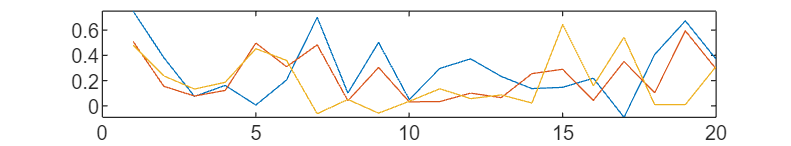

%3.3 

plot(D_prim')

min(min(D_prim'))

ans = -0.0912

It has negative values (°ー°〃)

%3.4 
minD = min(min(D_prim));
maxD = max(max(D_prim));

Dscaled = (D_prim(:,:,:) - minD) / (maxD - minD)

Dscaled =     1.0000    0.5629    0.1968    0.3007    0.1156    0.3517    0.9420    0.2286    0.7059    0.1674    0.4613    0.5510    0.3854    0.2707    0.2824    0.3687         0    0.5918    0.9094    0.5493
    0.7153    0.2921    0.2005    0.2534    0.7004    0.4768    0.6829    0.1560    0.4697    0.1455    0.1486    0.2280    0.1853    0.4119    0.4533    0.1592    0.5264    0.2309    0.8153    0.4563
    0.6796    0.3901    0.2664    0.3298    0.6469    0.5363    0.0336    0.1682    0.0390    0.1507    0.2692    0.1759    0.2111    0.1345    0.8726    0.2963    0.7548    0.1189    0.1194    0.4788


min(min(Dscaled))

ans = 0

max(max(Dscaled))

ans = 1

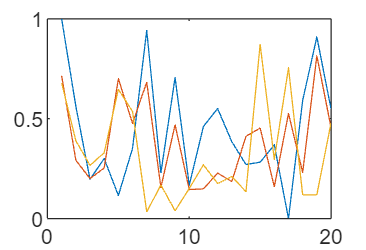

plot(Dscaled')


Sscaled = DLP * Dscaled;
Sxyzscaled = ( k * Sscaled' * xyz)'

Sxyzscaled =    91.4919   45.4932   23.9742   32.1430   56.3154   50.6520   74.5993   20.7517   53.8348   17.4854   31.2172   37.1975   29.2109   35.9382   53.4005   28.8171   44.3694   37.7800   82.4434   55.8851
   93.2701   42.8672   25.1164   32.8415   71.5842   56.0035   81.7366   20.8081   57.7132   18.2982   26.5707   34.5143   27.4177   43.8759   56.1978   25.7113   54.9010   35.0451   93.6231   58.0055
   85.5787   47.0413   30.0938   37.9614   72.6446   61.3013   24.6817   20.6224   19.0786   18.1676   32.3809   26.0499   26.7863   22.1977   91.2466   34.0477   78.4788   21.2755   34.4511   57.8014



[Mean, Max] = calcDeltaE(XYZ_ref', Sxyzscaled')

Mean = 17.4072

Max = 24.8719

Dclamped = D_prim;
Dclamped(Dclamped > 1.0) = 1.0;
Dclamped(Dclamped < 0) = 0;
Dclamped = DLP * Dclamped;

Sxyzclamped = (k * Dclamped' * xyz)';
[Mean, Max] = calcDeltaE(XYZ_ref', Sxyzclamped')

Mean = 2.8360

Max = 17.8740

Differance using normalisation but same values using clamping.

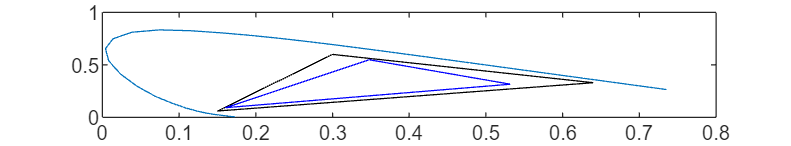

%3.5 
clf
plot_chrom_sRGB(Acrt)

%plot_chrom_sRGB(Sres)


We can scale to fit the gamut, clamp and use refrence values. 

%3.6
clf
OG_colour = (chips20.* CIED65);
Swow = (k * OG_colour * xyz)

Swow =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085


XYZ_ref_TEMP = XYZ_ref';

%plot(Sscaled)


[L_est, a_est, b_est] = xyz2lab(Swow(:,1),Swow(:,2),Swow(:,3));

[L_ref, a_ref, b_ref] = xyz2lab(XYZ_ref_TEMP(:,1), XYZ_ref_TEMP(:,2),XYZ_ref_TEMP(:,3));

L_diff = L_ref - L_est;
a_diff = a_ref - a_est;
b_diff = b_ref - b_est;
distance = sqrt(L_diff.^2 + a_diff.^2 + b_diff.^2)

distance = 1.0e-12 *

    0.0555
    0.0569
    0.0436
         0
         0
    0.1124
    0.0586
    0.0115
    0.1198
    0.0136



[minni, index] = min(distance)

minni = 0

index = 4


XYZ_ref_TEMP(index,:)

ans =    17.0944   16.8158   20.9340


Swow(index,:)

ans =    17.0944   16.8158   20.9340


400:5:700

ans =    400   405   410   415   420   425   430   435   440   445   450   455   460   465   470   475   480   485   490   495   500   505   510   515   520   525   530   535   540   545   550   555   560   565   570   575   580   585   590   595   600   605   610   615   620   625   630   635   640   645


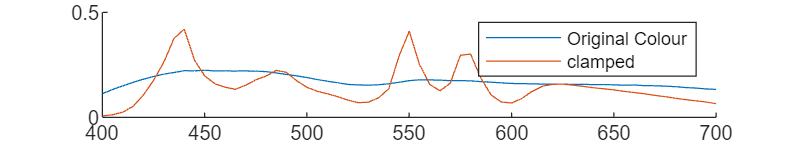

hold on
%plot(400:5:700, XYZ_ref_TEMP )
plot(400:5:700, OG_colour(index,:))
plot(400:5:700, Dclamped(:,index)')
legend('Original Colour', 'clamped')

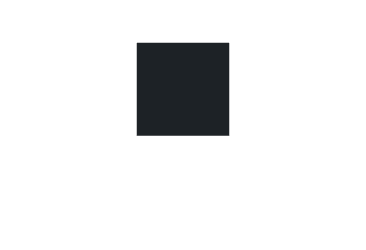

clf
showRGB(OG_colour(index,:))

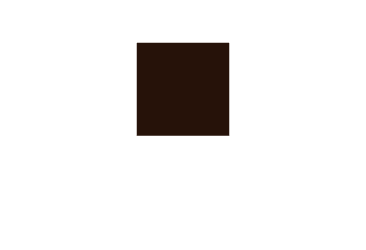

showRGB(Dclamped(index,:))